# Quantum Information Science HW P1

Harris A. Ransom

10/09/2024

### Question 1

H = [0 0 0 1 1 1 1
     0 1 1 0 0 1 1
     1 0 1 0 1 0 1];
HT = H'

HT =      0     0     1
     0     1     0
     0     1     1
     1     0     0
     1     0     1
     1     1     0
     1     1     1


zeroVec = [0, 0, 0];
c = [];
% Goal: Find c*HT = B
for i = 0:(2^7 - 1) 
    ci = dec2bin(i, 7)-'0';
    b = [];
    for j = 1:3
        bi = mod(dot(ci, HT(:,j)), 2);
        b(end+1) = bi;
    end
    if (all(zeroVec == b))
        c = cat(1, c, ci);
    end
end
c

c =      0     0     0     0     0     0     0
     0     0     0     1     1     1     1
     0     0     1     0     1     1     0
     0     0     1     1     0     0     1
     0     1     0     0     1     0     1
     0     1     0     1     0     1     0
     0     1     1     0     0     1     1
     0     1     1     1     1     0     0
     1     0     0     0     0     1     1
     1     0     0     1     1     0     0


### Question 2

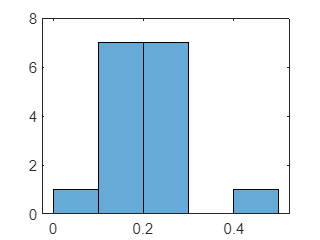

[rows, cols] = size(c);

count = zeros(1, rows);
for i = 1:rows
    for j = 1:cols
        if (c(i,j) == 1)
            count(i) = count(i) + 1;
        end
    end
end
normalizedHammingWeights = count ./ rows;
histogram(normalizedHammingWeights)

### Question 3

### Question 4